clear
clc

% cd frames\sick1\

% ///////////////////// INPUT \\\\\\\\\\\\\\\\\\\\\\\

prompt = 'Type in the name of the video (without the video extension): ';
folderName = input(prompt,'s');

prompt = ['Choose the segmentation algorithm:\n    ' ...
    '1) Own implementation of segmentation based on histogram binarization\n    ' ...
    '2) Segementation based on adaptive binarization\n    ' ...
    '3) Watershed segmentation\n\n'];
implementation = input(prompt);

folderPath = '';
filePath = ''; 
switch implementation
    case 1
        folderPath = ['binResults_' folderName]
        filePath = [folderPath '\binSegmentation_']
    case 2
        folderPath = ['adaptiveResults_' folderName]
        filePath = [folderPath '\adaptiveSegmentation_']
    case 3
        folderPath = ['watershedResults_' folderName]
        filePath = [folderPath '\watershedSegmentation_']
    case 4
        folderPath = ['lightResults_' folderName]
        filePath = [folderPath '\lightSegmentation_']
    otherwise
        errordlg('Choose a valid segmentation algorithm','Input Error')
        return
end

folderPath = 'adaptiveResults_sick1'

filePath = 'adaptiveResults_sick1\adaptiveSegmentation_'


prompt = ['Choose the segmentation feature: \n    ' ...
    '1) Redness\n    ' ...
    '2) Gray level\n    ' ...
    '3) Saturation\n    ' ...
    '4) Lightness (similar to gray level, but obtaining the L value from the HSL color scheme)\n\n'];
feature = input(prompt);

if exist(folderPath, 'dir')
    rmdir(folderPath,'s');
end
mkdir(folderPath);

prompt = 'Choose the number of the inital frame:';
initalFrame = input(prompt);
prompt = 'Choose the number of the final frame:';
finalFrame = input(prompt);

% Global Variables 
global S frameIx  previousThreshold previousCentroid
S = dir(fullfile(['.\' folderName '\'],'*.jpg'));
S = natsortfiles(S);

frames = {};
discardedFrames = {};

apertures = [];
aperture = -1;
areas = [];

previousThreshold = -1;
previousAperture = -1;
previousCentroid = [0 0];
minimumAperture = 7;
maximumConsecutiveMisses = 2;
consecutiveMisses = 0; % Counter of the number of consecutive misses
apertureThreshold = 0.8; % Scalar from 0 to 1


% initializing progress bar
f = waitbar(0,'Obtaining frames...');
for frameIx = initalFrame:finalFrame
    
    frameName = fullfile(['.\' folderName],S(frameIx).name)
    frame = imread(frameName);
    
    % updating progress bar
    percentage = (frameIx - initalFrame)/(finalFrame - initalFrame);
    waitbar(percentage,f,'Processing frames...'); 
    validFrame = true;

%     figure
%     imshow(frame);
%     title('Original Frame');
    
    % //////// PREPROCESSING \\\\\\\\\\
    % ------- Image Cropping ----------
    frameCropped = imcrop(frame,[168,54,387,458]);
%     figure
%     imshow(frameCropped);
%     title('Cropped Frame');
    % ---------------------------------
    
    % //////// BEST FEATURES \\\\\\\\\\
    % ----------- Redness -------------
    frameRChannel = frameCropped(:,:,1);
    % Create an all black channel.
    allBlack = zeros(size(frameCropped, 1), size(frameCropped, 2), 'uint8');
    % Create a color version of the Red Channel
    frameRed = cat(3, frameRChannel, allBlack, allBlack);
    % Print red channel
%     imshow(frameRed);
%     title('Red Channel only');
    % ---------------------------------
    
    % ----------- Grayness ------------
    frameGray = rgb2gray(frameCropped);
%     imshow(frameGray);
%     title('Gray scale');
    % ---------------------------------
    
    % ----------- Saturation ----------
    framehsv = rgb2hsv(frameCropped);
    frameSaturation = framehsv(:,:,2);
%     figure
%     imshow(frameSaturation)
    frameSaturation = abs(frameSaturation - 1);
    % ---------------------------------
    
    % ------------ Light --------------
    hslFrame = rgb2hsl(im2double(frameCropped));
    frameLightness = hslFrame(:,:,3);
    % ---------------------------------
    
    % \\\\\\\\\\\\\\\|/////////////////
    
    preProcessedFrame = [];
    % Filterage of frame
    switch  feature
        case 1
            preProcessedFrame = openCloseByReconstruction(frameRChannel);
        case 2
            preProcessedFrame = openCloseByReconstruction(frameGray);
        case 3
            preProcessedFrame = openCloseByReconstruction(frameSaturation);
        case 4
            preProcessedFrame = openCloseByReconstruction(frameLightness);
    end
    
%     imshow(preProcessedFrame);
%     title('Preprocessed Frame')

    % \\\\\\\\\\\\\\\|/////////////////
    
    % ///////// SEGMENTATION \\\\\\\\\\
        
    binFrame = [];
    switch implementation
        case 1
            try
                % Hist binaritzation
                binFrame = binBinarization(preProcessedFrame,10);
            catch
                sprintf('Error during binBinarization in frame %d',frameIx)
                validFrame = false;
            end
        case 2
            try
                % Adaptive binarization
                binFrame = imbinarize(preProcessedFrame,"adaptive", ...
                    "ForegroundPolarity","bright","Sensitivity",0.66);
                binFrame = ~binFrame;
            catch
                sprintf('Error during adaptiveBinarization in frame %d',frameIx)
                validFrame = false;
            end
        case 3
            try
                % Watershed segmentation
                binFrame = watershedSegmentation(preProcessedFrame, frameCropped, frameRChannel);
            catch
                sprintf('Error during Watershed segmentation in frame %d',frameIx)
                validFrame = false;
            end
    end
    
%     figure
%     imshow(binFrame)
    
    % Otsu binarization
%     level = graythresh(preProcessedFrame);
%     binFrameOtsu = imbinarize(preProcessedFrame,level);

    % ---------------------------------
    % \\\\\\\\\\\\\\\|/////////////////
    
    % //////// POSTPROCESSING \\\\\\\\\\
    try
        if validFrame
            closeDiffBlobFrame = getSegment(binFrame);
        end
    catch
        sprintf('Error during funciton getSegmet of frame %d', frameIx)
        validFrame = false;
    end
%     figure
%     imshow(closeDiffBlobFrame)
    % \\\\\\\\\\\\\\\|/////////////////
    
    % Getting the area
    if validFrame
        maxDiffArea = bwarea(closeDiffBlobFrame);
    end
    
    if validFrame
        try
            aperture = getStenosisDegree(frameCropped, closeDiffBlobFrame, ['\' filePath]);
        catch
            sprintf('Error while getting the stenosis degree of frame %f', frameIx)
        end
        if previousAperture == -1 && aperture > minimumAperture
            previousAperture = aperture;
        elseif aperture < minimumAperture
            validFrame = false;
        end
    end
    % \\\\\\\\\\\\\\\|/////////////////
        
    % Adaptive result
%     secondFig = figure('visible','off');
%     segmentationOutline(frameCropped, closeAdaptiveBlobFrame);
%     title('Segmentation outline based on adaptive binarization');
%     saveas(secondFig,[pwd '\adaptiveResultsSick1\adaptiveSegmentation_' S(frameIx).name]);
    
    % Watershed result
%     thirdFig = figure('visible','off');
%     segmentationOutline(frameCropped, watershedSegmentation);
%     title('Segmentation outline based on watersheding with local minimum and maxima');
%     saveas(thirdFig,[pwd '\watershedResultsSick1\watershedSegmentation_' S(frameIx).name]);

    % ---------- Saving results -------------- %
    validAperture = false;
    if validFrame
        if aperture < previousAperture + previousAperture*apertureThreshold && ...
            aperture > previousAperture - previousAperture*apertureThreshold
        validAperture = true;
        end 
    end
    
    if (validFrame && validAperture) || (consecutiveMisses >= maximumConsecutiveMisses && aperture > minimumAperture)
        frames{end + 1} = S(frameIx).name;
        apertures = [apertures aperture];
        previousAperture = aperture;
        validFrame = true;
        consecutiveMisses = 0;
    else
        previousThreshold = - 1;
        previousAperture
        aperture
        discardedFrames{end + 1}= S(frameIx).name;
        consecutiveMisses = consecutiveMisses + 1;
    end
    % ---------------------------------------- %
end 

frameName = '.\sick1\1.jpg'

frameName = '.\sick1\2.jpg'

frameName = '.\sick1\3.jpg'

frameName = '.\sick1\4.jpg'

frameName = '.\sick1\5.jpg'

frameName = '.\sick1\6.jpg'

frameName = '.\sick1\7.jpg'

frameName = '.\sick1\8.jpg'

frameName = '.\sick1\9.jpg'

frameName = '.\sick1\10.jpg'

frameName = '.\sick1\11.jpg'

frameName = '.\sick1\12.jpg'

frameName = '.\sick1\13.jpg'

frameName = '.\sick1\14.jpg'

frameName = '.\sick1\15.jpg'

frameName = '.\sick1\16.jpg'

frameName = '.\sick1\17.jpg'

frameName = '.\sick1\18.jpg'

frameName = '.\sick1\19.jpg'

frameName = '.\sick1\20.jpg'

frameName = '.\sick1\21.jpg'

frameName = '.\sick1\22.jpg'

frameName = '.\sick1\23.jpg'

frameName = '.\sick1\24.jpg'

frameName = '.\sick1\25.jpg'

frameName = '.\sick1\26.jpg'

frameName = '.\sick1\27.jpg'

frameName = '.\sick1\28.jpg'

frameName = '.\sick1\29.jpg'

frameName = '.\sick1\30.jpg'

frameName = '.\sick1\31.jpg'

frameName = '.\sick1\32.jpg'

frameName = '.\sick1\33.jpg'

frameName = '.\sick1\34.jpg'

frameName = '.\sick1\35.jpg'

frameName = '.\sick1\36.jpg'

frameName = '.\sick1\37.jpg'

frameName = '.\sick1\38.jpg'

frameName = '.\sick1\39.jpg'

frameName = '.\sick1\40.jpg'

frameName = '.\sick1\41.jpg'

frameName = '.\sick1\42.jpg'

frameName = '.\sick1\43.jpg'

frameName = '.\sick1\44.jpg'

frameName = '.\sick1\45.jpg'

frameName = '.\sick1\46.jpg'

frameName = '.\sick1\47.jpg'

frameName = '.\sick1\48.jpg'

frameName = '.\sick1\49.jpg'

frameName = '.\sick1\50.jpg'

frameName = '.\sick1\51.jpg'

frameName = '.\sick1\52.jpg'

frameName = '.\sick1\53.jpg'

frameName = '.\sick1\54.jpg'

frameName = '.\sick1\55.jpg'

frameName = '.\sick1\56.jpg'

frameName = '.\sick1\57.jpg'

frameName = '.\sick1\58.jpg'

frameName = '.\sick1\59.jpg'

frameName = '.\sick1\60.jpg'

frameName = '.\sick1\61.jpg'

frameName = '.\sick1\62.jpg'

frameName = '.\sick1\63.jpg'

frameName = '.\sick1\64.jpg'

frameName = '.\sick1\65.jpg'

frameName = '.\sick1\66.jpg'

frameName = '.\sick1\67.jpg'

frameName = '.\sick1\68.jpg'

frameName = '.\sick1\69.jpg'

frameName = '.\sick1\70.jpg'

frameName = '.\sick1\71.jpg'

frameName = '.\sick1\72.jpg'

frameName = '.\sick1\73.jpg'

frameName = '.\sick1\74.jpg'

frameName = '.\sick1\75.jpg'

frameName = '.\sick1\76.jpg'

frameName = '.\sick1\77.jpg'

frameName = '.\sick1\78.jpg'

frameName = '.\sick1\79.jpg'

frameName = '.\sick1\80.jpg'

frameName = '.\sick1\81.jpg'

frameName = '.\sick1\82.jpg'

frameName = '.\sick1\83.jpg'

previousAperture = 76.1577

aperture = 149.1643

frameName = '.\sick1\84.jpg'

frameName = '.\sick1\85.jpg'

frameName = '.\sick1\86.jpg'

frameName = '.\sick1\87.jpg'

frameName = '.\sick1\88.jpg'

frameName = '.\sick1\89.jpg'

frameName = '.\sick1\90.jpg'

frameName = '.\sick1\91.jpg'

frameName = '.\sick1\92.jpg'

frameName = '.\sick1\93.jpg'

frameName = '.\sick1\94.jpg'

frameName = '.\sick1\95.jpg'

frameName = '.\sick1\96.jpg'

frameName = '.\sick1\97.jpg'

frameName = '.\sick1\98.jpg'

frameName = '.\sick1\99.jpg'

frameName = '.\sick1\100.jpg'

frameName = '.\sick1\101.jpg'

frameName = '.\sick1\102.jpg'

frameName = '.\sick1\103.jpg'

frameName = '.\sick1\104.jpg'

frameName = '.\sick1\105.jpg'

frameName = '.\sick1\106.jpg'

frameName = '.\sick1\107.jpg'

frameName = '.\sick1\108.jpg'

frameName = '.\sick1\109.jpg'

frameName = '.\sick1\110.jpg'

frameName = '.\sick1\111.jpg'

frameName = '.\sick1\112.jpg'

frameName = '.\sick1\113.jpg'

frameName = '.\sick1\114.jpg'

frameName = '.\sick1\115.jpg'

frameName = '.\sick1\116.jpg'

frameName = '.\sick1\117.jpg'

frameName = '.\sick1\118.jpg'

frameName = '.\sick1\119.jpg'

frameName = '.\sick1\120.jpg'

frameName = '.\sick1\121.jpg'

frameName = '.\sick1\122.jpg'

frameName = '.\sick1\123.jpg'

frameName = '.\sick1\124.jpg'

frameName = '.\sick1\125.jpg'

frameName = '.\sick1\126.jpg'

frameName = '.\sick1\127.jpg'

frameName = '.\sick1\128.jpg'

frameName = '.\sick1\129.jpg'

frameName = '.\sick1\130.jpg'

frameName = '.\sick1\131.jpg'

frameName = '.\sick1\132.jpg'

frameName = '.\sick1\133.jpg'

frameName = '.\sick1\134.jpg'

frameName = '.\sick1\135.jpg'

frameName = '.\sick1\136.jpg'

frameName = '.\sick1\137.jpg'

frameName = '.\sick1\138.jpg'

frameName = '.\sick1\139.jpg'

frameName = '.\sick1\140.jpg'

frameName = '.\sick1\141.jpg'

frameName = '.\sick1\142.jpg'

frameName = '.\sick1\143.jpg'

frameName = '.\sick1\144.jpg'

frameName = '.\sick1\145.jpg'

frameName = '.\sick1\146.jpg'

frameName = '.\sick1\147.jpg'

frameName = '.\sick1\148.jpg'

frameName = '.\sick1\149.jpg'

frameName = '.\sick1\150.jpg'

frameName = '.\sick1\151.jpg'

frameName = '.\sick1\152.jpg'

frameName = '.\sick1\153.jpg'

frameName = '.\sick1\154.jpg'

frameName = '.\sick1\155.jpg'

frameName = '.\sick1\156.jpg'

frameName = '.\sick1\157.jpg'

frameName = '.\sick1\158.jpg'

frameName = '.\sick1\159.jpg'

frameName = '.\sick1\160.jpg'

frameName = '.\sick1\161.jpg'

frameName = '.\sick1\162.jpg'

frameName = '.\sick1\163.jpg'

frameName = '.\sick1\164.jpg'

frameName = '.\sick1\165.jpg'

previousAperture = 42.1545

aperture = 86.3771

frameName = '.\sick1\166.jpg'

previousAperture = 42.1545

aperture = 82.2192

frameName = '.\sick1\167.jpg'

frameName = '.\sick1\168.jpg'

frameName = '.\sick1\169.jpg'

frameName = '.\sick1\170.jpg'

frameName = '.\sick1\171.jpg'

frameName = '.\sick1\172.jpg'

frameName = '.\sick1\173.jpg'

frameName = '.\sick1\174.jpg'

frameName = '.\sick1\175.jpg'

frameName = '.\sick1\176.jpg'

previousAperture = 15.5242

aperture = 6.0828

frameName = '.\sick1\177.jpg'

frameName = '.\sick1\178.jpg'

previousAperture = 7.0711

aperture = 18.4391

frameName = '.\sick1\179.jpg'

previousAperture = 7.0711

aperture = 76.0592

frameName = '.\sick1\180.jpg'

frameName = '.\sick1\181.jpg'

ans = 'Error during funciton getSegmet of frame 181'

previousAperture = 20.0998

aperture = 20.0998

frameName = '.\sick1\182.jpg'

frameName = '.\sick1\183.jpg'

frameName = '.\sick1\184.jpg'

previousAperture = 40.4969

aperture = 81.6149

frameName = '.\sick1\185.jpg'

previousAperture = 40.4969

aperture = 101.1237

frameName = '.\sick1\186.jpg'

frameName = '.\sick1\187.jpg'

frameName = '.\sick1\188.jpg'

frameName = '.\sick1\189.jpg'

previousAperture = 130.1153

aperture = 24.0416

frameName = '.\sick1\190.jpg'

frameName = '.\sick1\191.jpg'

previousAperture = 44.0114

aperture = 83.1505

frameName = '.\sick1\192.jpg'

previousAperture = 44.0114

aperture = 100.1798

frameName = '.\sick1\193.jpg'

frameName = '.\sick1\194.jpg'

frameName = '.\sick1\195.jpg'

frameName = '.\sick1\196.jpg'

frameName = '.\sick1\197.jpg'

previousAperture = 27.2029

aperture = 50.4480

frameName = '.\sick1\198.jpg'

previousAperture = 27.2029

aperture = 84.5281

frameName = '.\sick1\199.jpg'

frameName = '.\sick1\200.jpg'

frameName = '.\sick1\201.jpg'

frameName = '.\sick1\202.jpg'

frameName = '.\sick1\203.jpg'

frameName = '.\sick1\204.jpg'

frameName = '.\sick1\205.jpg'

frameName = '.\sick1\206.jpg'

frameName = '.\sick1\207.jpg'

frameName = '.\sick1\208.jpg'

previousAperture = 58.1378

aperture = 10.2956

frameName = '.\sick1\209.jpg'

frameName = '.\sick1\210.jpg'

frameName = '.\sick1\211.jpg'

previousAperture = 13.4164

aperture = 45.8912

frameName = '.\sick1\212.jpg'

previousAperture = 13.4164

aperture = 118.2582

frameName = '.\sick1\213.jpg'

frameName = '.\sick1\214.jpg'

frameName = '.\sick1\215.jpg'

frameName = '.\sick1\216.jpg'

frameName = '.\sick1\217.jpg'

frameName = '.\sick1\218.jpg'

previousAperture = 49.6488

aperture = 105.0809

frameName = '.\sick1\219.jpg'

previousAperture = 49.6488

aperture = 112.4500

frameName = '.\sick1\220.jpg'

frameName = '.\sick1\221.jpg'

frameName = '.\sick1\222.jpg'

frameName = '.\sick1\223.jpg'

frameName = '.\sick1\224.jpg'

frameName = '.\sick1\225.jpg'

previousAperture = 13.8924

aperture = 6.0828

frameName = '.\sick1\226.jpg'

previousAperture = 13.8924

aperture = 35.2278

frameName = '.\sick1\227.jpg'

frameName = '.\sick1\228.jpg'

frameName = '.\sick1\229.jpg'

frameName = '.\sick1\230.jpg'

frameName = '.\sick1\231.jpg'

frameName = '.\sick1\232.jpg'

frameName = '.\sick1\233.jpg'

frameName = '.\sick1\234.jpg'

frameName = '.\sick1\235.jpg'

frameName = '.\sick1\236.jpg'

frameName = '.\sick1\237.jpg'

frameName = '.\sick1\238.jpg'

frameName = '.\sick1\239.jpg'

previousAperture = 132.1968

aperture = 245.1551

frameName = '.\sick1\240.jpg'

previousAperture = 132.1968

aperture = 277.8003

frameName = '.\sick1\241.jpg'

frameName = '.\sick1\242.jpg'

frameName = '.\sick1\243.jpg'

frameName = '.\sick1\244.jpg'

frameName = '.\sick1\245.jpg'

frameName = '.\sick1\246.jpg'

frameName = '.\sick1\247.jpg'

frameName = '.\sick1\248.jpg'

frameName = '.\sick1\249.jpg'

frameName = '.\sick1\250.jpg'

frameName = '.\sick1\251.jpg'

frameName = '.\sick1\252.jpg'

frameName = '.\sick1\253.jpg'

frameName = '.\sick1\254.jpg'

frameName = '.\sick1\255.jpg'

frameName = '.\sick1\256.jpg'

frameName = '.\sick1\257.jpg'

frameName = '.\sick1\258.jpg'

frameName = '.\sick1\259.jpg'

frameName = '.\sick1\260.jpg'

frameName = '.\sick1\261.jpg'

frameName = '.\sick1\262.jpg'

frameName = '.\sick1\263.jpg'

frameName = '.\sick1\264.jpg'

frameName = '.\sick1\265.jpg'

frameName = '.\sick1\266.jpg'

frameName = '.\sick1\267.jpg'

frameName = '.\sick1\268.jpg'

frameName = '.\sick1\269.jpg'

previousAperture = 81.4923

aperture = 148.0844

frameName = '.\sick1\270.jpg'

previousAperture = 81.4923

aperture = 155.9134

frameName = '.\sick1\271.jpg'

frameName = '.\sick1\272.jpg'

frameName = '.\sick1\273.jpg'

frameName = '.\sick1\274.jpg'

frameName = '.\sick1\275.jpg'

frameName = '.\sick1\276.jpg'

frameName = '.\sick1\277.jpg'

frameName = '.\sick1\278.jpg'

frameName = '.\sick1\279.jpg'

frameName = '.\sick1\280.jpg'

frameName = '.\sick1\281.jpg'

frameName = '.\sick1\282.jpg'

frameName = '.\sick1\283.jpg'

frameName = '.\sick1\284.jpg'

frameName = '.\sick1\285.jpg'

frameName = '.\sick1\286.jpg'

frameName = '.\sick1\287.jpg'

frameName = '.\sick1\288.jpg'

frameName = '.\sick1\289.jpg'

frameName = '.\sick1\290.jpg'

frameName = '.\sick1\291.jpg'

ans = 'Error while getting the stenosis degree of frame 291.000000'

frameName = '.\sick1\292.jpg'

ans = 'Error during funciton getSegmet of frame 292'

previousAperture = 29.0689

aperture = 29.0689

frameName = '.\sick1\293.jpg'

previousAperture = 29.0689

aperture = 5

frameName = '.\sick1\294.jpg'

frameName = '.\sick1\295.jpg'

frameName = '.\sick1\296.jpg'

frameName = '.\sick1\297.jpg'

frameName = '.\sick1\298.jpg'

frameName = '.\sick1\299.jpg'

previousAperture = 57.4891

aperture = 130.3879

frameName = '.\sick1\300.jpg'

frameName = '.\sick1\301.jpg'

frameName = '.\sick1\302.jpg'

frameName = '.\sick1\303.jpg'

frameName = '.\sick1\304.jpg'

frameName = '.\sick1\305.jpg'

previousAperture = 13.8924

aperture = 66.4831

frameName = '.\sick1\306.jpg'

previousAperture = 13.8924

aperture = 67.0671

frameName = '.\sick1\307.jpg'

frameName = '.\sick1\308.jpg'

frameName = '.\sick1\309.jpg'

frameName = '.\sick1\310.jpg'

frameName = '.\sick1\311.jpg'

frameName = '.\sick1\312.jpg'

frameName = '.\sick1\313.jpg'

frameName = '.\sick1\314.jpg'

frameName = '.\sick1\315.jpg'

frameName = '.\sick1\316.jpg'

frameName = '.\sick1\317.jpg'

frameName = '.\sick1\318.jpg'

frameName = '.\sick1\319.jpg'

frameName = '.\sick1\320.jpg'

frameName = '.\sick1\321.jpg'

frameName = '.\sick1\322.jpg'

frameName = '.\sick1\323.jpg'

frameName = '.\sick1\324.jpg'

frameName = '.\sick1\325.jpg'

frameName = '.\sick1\326.jpg'

frameName = '.\sick1\327.jpg'

frameName = '.\sick1\328.jpg'

frameName = '.\sick1\329.jpg'

frameName = '.\sick1\330.jpg'

frameName = '.\sick1\331.jpg'

frameName = '.\sick1\332.jpg'

ans = 'Error during funciton getSegmet of frame 332'

previousAperture = 84.5281

aperture = 84.5281

frameName = '.\sick1\333.jpg'

frameName = '.\sick1\334.jpg'

previousAperture = 23.3452

aperture = 96.4624

frameName = '.\sick1\335.jpg'

frameName = '.\sick1\336.jpg'

previousAperture = 26.2488

aperture = 111.4002

frameName = '.\sick1\337.jpg'

previousAperture = 26.2488

aperture = 109.9318

frameName = '.\sick1\338.jpg'

ans = 'Error during funciton getSegmet of frame 338'

frameName = '.\sick1\339.jpg'

frameName = '.\sick1\340.jpg'

ans = 'Error during funciton getSegmet of frame 340'

previousAperture = 27.2947

aperture = 27.2947

frameName = '.\sick1\341.jpg'

ans = 'Error during funciton getSegmet of frame 341'

previousAperture = 27.2947

aperture = 27.2947

frameName = '.\sick1\342.jpg'

frameName = '.\sick1\343.jpg'

frameName = '.\sick1\344.jpg'

previousAperture = 7.0711

aperture = 19.6469

frameName = '.\sick1\345.jpg'

previousAperture = 7.0711

aperture = 23.0868

frameName = '.\sick1\346.jpg'

frameName = '.\sick1\347.jpg'

frameName = '.\sick1\348.jpg'

previousAperture = 10.2956

aperture = 127.2831

frameName = '.\sick1\349.jpg'

frameName = '.\sick1\350.jpg'

previousAperture = 12.0830

aperture = 31.7648

frameName = '.\sick1\351.jpg'

previousAperture = 12.0830

aperture = 0

frameName = '.\sick1\352.jpg'

frameName = '.\sick1\353.jpg'

previousAperture = 10

aperture = 31.5753

frameName = '.\sick1\354.jpg'

previousAperture = 10

aperture = 138.2208

frameName = '.\sick1\355.jpg'

frameName = '.\sick1\356.jpg'

frameName = '.\sick1\357.jpg'

frameName = '.\sick1\358.jpg'

frameName = '.\sick1\359.jpg'

frameName = '.\sick1\360.jpg'

frameName = '.\sick1\361.jpg'

frameName = '.\sick1\362.jpg'

frameName = '.\sick1\363.jpg'

frameName = '.\sick1\364.jpg'

frameName = '.\sick1\365.jpg'

frameName = '.\sick1\366.jpg'

frameName = '.\sick1\367.jpg'

frameName = '.\sick1\368.jpg'

frameName = '.\sick1\369.jpg'

frameName = '.\sick1\370.jpg'

frameName = '.\sick1\371.jpg'

frameName = '.\sick1\372.jpg'

frameName = '.\sick1\373.jpg'

frameName = '.\sick1\374.jpg'

frameName = '.\sick1\375.jpg'

frameName = '.\sick1\376.jpg'

frameName = '.\sick1\377.jpg'

frameName = '.\sick1\378.jpg'

frameName = '.\sick1\379.jpg'

frameName = '.\sick1\380.jpg'

frameName = '.\sick1\381.jpg'

frameName = '.\sick1\382.jpg'

frameName = '.\sick1\383.jpg'

frameName = '.\sick1\384.jpg'

frameName = '.\sick1\385.jpg'

frameName = '.\sick1\386.jpg'

frameName = '.\sick1\387.jpg'

frameName = '.\sick1\388.jpg'

frameName = '.\sick1\389.jpg'

frameName = '.\sick1\390.jpg'

frameName = '.\sick1\391.jpg'

frameName = '.\sick1\392.jpg'

frameName = '.\sick1\393.jpg'

frameName = '.\sick1\394.jpg'

frameName = '.\sick1\395.jpg'

frameName = '.\sick1\396.jpg'

frameName = '.\sick1\397.jpg'

frameName = '.\sick1\398.jpg'

frameName = '.\sick1\399.jpg'

frameName = '.\sick1\400.jpg'

frameName = '.\sick1\401.jpg'

frameName = '.\sick1\402.jpg'

frameName = '.\sick1\403.jpg'

frameName = '.\sick1\404.jpg'

frameName = '.\sick1\405.jpg'

frameName = '.\sick1\406.jpg'

frameName = '.\sick1\407.jpg'

frameName = '.\sick1\408.jpg'

frameName = '.\sick1\409.jpg'

frameName = '.\sick1\410.jpg'

frameName = '.\sick1\411.jpg'

frameName = '.\sick1\412.jpg'

frameName = '.\sick1\413.jpg'

frameName = '.\sick1\414.jpg'

frameName = '.\sick1\415.jpg'

frameName = '.\sick1\416.jpg'

frameName = '.\sick1\417.jpg'

frameName = '.\sick1\418.jpg'

frameName = '.\sick1\419.jpg'

frameName = '.\sick1\420.jpg'

frameName = '.\sick1\421.jpg'

frameName = '.\sick1\422.jpg'

frameName = '.\sick1\423.jpg'

frameName = '.\sick1\424.jpg'

frameName = '.\sick1\425.jpg'

frameName = '.\sick1\426.jpg'

frameName = '.\sick1\427.jpg'

frameName = '.\sick1\428.jpg'

frameName = '.\sick1\429.jpg'

frameName = '.\sick1\430.jpg'

frameName = '.\sick1\431.jpg'

frameName = '.\sick1\432.jpg'

frameName = '.\sick1\433.jpg'

frameName = '.\sick1\434.jpg'

frameName = '.\sick1\435.jpg'

frameName = '.\sick1\436.jpg'

frameName = '.\sick1\437.jpg'

frameName = '.\sick1\438.jpg'

frameName = '.\sick1\439.jpg'

frameName = '.\sick1\440.jpg'

frameName = '.\sick1\441.jpg'

frameName = '.\sick1\442.jpg'

frameName = '.\sick1\443.jpg'

frameName = '.\sick1\444.jpg'

frameName = '.\sick1\445.jpg'

frameName = '.\sick1\446.jpg'

frameName = '.\sick1\447.jpg'

frameName = '.\sick1\448.jpg'

frameName = '.\sick1\449.jpg'

frameName = '.\sick1\450.jpg'

frameName = '.\sick1\451.jpg'

frameName = '.\sick1\452.jpg'

previousAperture = 22.1359

aperture = 54.8179

frameName = '.\sick1\453.jpg'

frameName = '.\sick1\454.jpg'

frameName = '.\sick1\455.jpg'

frameName = '.\sick1\456.jpg'

frameName = '.\sick1\457.jpg'

frameName = '.\sick1\458.jpg'

frameName = '.\sick1\459.jpg'

frameName = '.\sick1\460.jpg'

frameName = '.\sick1\461.jpg'

frameName = '.\sick1\462.jpg'

frameName = '.\sick1\463.jpg'

frameName = '.\sick1\464.jpg'

previousAperture = 23.0868

aperture = 95.0789

frameName = '.\sick1\465.jpg'

frameName = '.\sick1\466.jpg'

frameName = '.\sick1\467.jpg'

frameName = '.\sick1\468.jpg'

frameName = '.\sick1\469.jpg'

frameName = '.\sick1\470.jpg'

frameName = '.\sick1\471.jpg'

frameName = '.\sick1\472.jpg'

frameName = '.\sick1\473.jpg'

frameName = '.\sick1\474.jpg'

frameName = '.\sick1\475.jpg'

previousAperture = 36.6879

aperture = 90.5207

frameName = '.\sick1\476.jpg'

previousAperture = 36.6879

aperture = 82.0061

frameName = '.\sick1\477.jpg'

frameName = '.\sick1\478.jpg'

frameName = '.\sick1\479.jpg'

frameName = '.\sick1\480.jpg'

frameName = '.\sick1\481.jpg'

frameName = '.\sick1\482.jpg'

frameName = '.\sick1\483.jpg'

frameName = '.\sick1\484.jpg'

frameName = '.\sick1\485.jpg'

frameName = '.\sick1\486.jpg'

frameName = '.\sick1\487.jpg'

frameName = '.\sick1\488.jpg'

frameName = '.\sick1\489.jpg'

frameName = '.\sick1\490.jpg'

frameName = '.\sick1\491.jpg'

frameName = '.\sick1\492.jpg'

frameName = '.\sick1\493.jpg'

frameName = '.\sick1\494.jpg'

frameName = '.\sick1\495.jpg'

frameName = '.\sick1\496.jpg'

frameName = '.\sick1\497.jpg'

frameName = '.\sick1\498.jpg'

frameName = '.\sick1\499.jpg'

frameName = '.\sick1\500.jpg'

frameName = '.\sick1\501.jpg'

frameName = '.\sick1\502.jpg'

frameName = '.\sick1\503.jpg'

frameName = '.\sick1\504.jpg'

frameName = '.\sick1\505.jpg'

frameName = '.\sick1\506.jpg'

frameName = '.\sick1\507.jpg'

frameName = '.\sick1\508.jpg'

frameName = '.\sick1\509.jpg'

frameName = '.\sick1\510.jpg'

frameName = '.\sick1\511.jpg'

frameName = '.\sick1\512.jpg'

previousAperture = 54.7449

aperture = 123.6851

frameName = '.\sick1\513.jpg'

frameName = '.\sick1\514.jpg'

frameName = '.\sick1\515.jpg'

frameName = '.\sick1\516.jpg'

frameName = '.\sick1\517.jpg'

frameName = '.\sick1\518.jpg'

frameName = '.\sick1\519.jpg'

frameName = '.\sick1\520.jpg'

frameName = '.\sick1\521.jpg'

frameName = '.\sick1\522.jpg'

frameName = '.\sick1\523.jpg'

frameName = '.\sick1\524.jpg'

frameName = '.\sick1\525.jpg'

frameName = '.\sick1\526.jpg'

frameName = '.\sick1\527.jpg'

frameName = '.\sick1\528.jpg'

frameName = '.\sick1\529.jpg'

frameName = '.\sick1\530.jpg'

frameName = '.\sick1\531.jpg'

frameName = '.\sick1\532.jpg'

frameName = '.\sick1\533.jpg'

frameName = '.\sick1\534.jpg'

frameName = '.\sick1\535.jpg'

frameName = '.\sick1\536.jpg'

frameName = '.\sick1\537.jpg'

frameName = '.\sick1\538.jpg'

frameName = '.\sick1\539.jpg'

frameName = '.\sick1\540.jpg'

frameName = '.\sick1\541.jpg'

frameName = '.\sick1\542.jpg'

frameName = '.\sick1\543.jpg'

frameName = '.\sick1\544.jpg'

frameName = '.\sick1\545.jpg'

frameName = '.\sick1\546.jpg'

frameName = '.\sick1\547.jpg'

frameName = '.\sick1\548.jpg'

frameName = '.\sick1\549.jpg'

frameName = '.\sick1\550.jpg'

frameName = '.\sick1\551.jpg'

frameName = '.\sick1\552.jpg'

frameName = '.\sick1\553.jpg'

frameName = '.\sick1\554.jpg'

frameName = '.\sick1\555.jpg'

frameName = '.\sick1\556.jpg'

frameName = '.\sick1\557.jpg'

frameName = '.\sick1\558.jpg'

frameName = '.\sick1\559.jpg'

frameName = '.\sick1\560.jpg'

frameName = '.\sick1\561.jpg'

frameName = '.\sick1\562.jpg'

frameName = '.\sick1\563.jpg'

frameName = '.\sick1\564.jpg'

frameName = '.\sick1\565.jpg'

frameName = '.\sick1\566.jpg'

frameName = '.\sick1\567.jpg'

frameName = '.\sick1\568.jpg'

frameName = '.\sick1\569.jpg'

frameName = '.\sick1\570.jpg'

previousAperture = 94.7259

aperture = 174.1407

frameName = '.\sick1\571.jpg'

frameName = '.\sick1\572.jpg'

frameName = '.\sick1\573.jpg'

frameName = '.\sick1\574.jpg'

frameName = '.\sick1\575.jpg'

frameName = '.\sick1\576.jpg'

frameName = '.\sick1\577.jpg'

frameName = '.\sick1\578.jpg'

frameName = '.\sick1\579.jpg'

frameName = '.\sick1\580.jpg'

frameName = '.\sick1\581.jpg'

frameName = '.\sick1\582.jpg'

frameName = '.\sick1\583.jpg'

frameName = '.\sick1\584.jpg'

frameName = '.\sick1\585.jpg'

frameName = '.\sick1\586.jpg'

frameName = '.\sick1\587.jpg'

frameName = '.\sick1\588.jpg'

frameName = '.\sick1\589.jpg'

frameName = '.\sick1\590.jpg'

frameName = '.\sick1\591.jpg'

frameName = '.\sick1\592.jpg'

frameName = '.\sick1\593.jpg'

frameName = '.\sick1\594.jpg'

frameName = '.\sick1\595.jpg'

frameName = '.\sick1\596.jpg'

frameName = '.\sick1\597.jpg'

frameName = '.\sick1\598.jpg'

frameName = '.\sick1\599.jpg'

frameName = '.\sick1\600.jpg'

frameName = '.\sick1\601.jpg'

frameName = '.\sick1\602.jpg'

frameName = '.\sick1\603.jpg'

frameName = '.\sick1\604.jpg'

frameName = '.\sick1\605.jpg'

frameName = '.\sick1\606.jpg'

frameName = '.\sick1\607.jpg'

frameName = '.\sick1\608.jpg'

frameName = '.\sick1\609.jpg'

frameName = '.\sick1\610.jpg'

frameName = '.\sick1\611.jpg'

frameName = '.\sick1\612.jpg'

frameName = '.\sick1\613.jpg'

frameName = '.\sick1\614.jpg'

frameName = '.\sick1\615.jpg'

frameName = '.\sick1\616.jpg'

previousAperture = 63.5689

aperture = 116.7604

frameName = '.\sick1\617.jpg'

frameName = '.\sick1\618.jpg'

frameName = '.\sick1\619.jpg'

frameName = '.\sick1\620.jpg'

frameName = '.\sick1\621.jpg'

frameName = '.\sick1\622.jpg'

frameName = '.\sick1\623.jpg'

frameName = '.\sick1\624.jpg'

frameName = '.\sick1\625.jpg'

frameName = '.\sick1\626.jpg'

frameName = '.\sick1\627.jpg'

frameName = '.\sick1\628.jpg'

frameName = '.\sick1\629.jpg'

frameName = '.\sick1\630.jpg'

frameName = '.\sick1\631.jpg'

frameName = '.\sick1\632.jpg'

frameName = '.\sick1\633.jpg'

frameName = '.\sick1\634.jpg'


% closing progress bar
close(f)

% ///////////// RESULTS \\\\\\\\\\\\\\\

T = table(frames',apertures')

T = 584×2 table
       Var1        Var2 
    __________    ______

    {'1.jpg' }    108.93
    {'2.jpg' }    112.36
    {'3.jpg' }    112.09
    {'4.jpg' }    115.13
    {'5.jpg' }    113.51
    {'6.jpg' }    112.36
    {'7.jpg' }    113.05
    {'8.jpg' }    110.86
    {'9.jpg' }    109.64
    {'10.jpg'}    106.48
    {'11.jpg'}    105.02
    {'12.jpg'}    105.99
    {'13.jpg'}    105.02
    {'14.jpg'}    106.23
    {'15.jpg'}    105.26
    {'16.jpg'}    106.48


% Standard Deviation of the valid apertures
variance = var(apertures)

variance = 3.8504e+03

standardDeviation = std(apertures)

standardDeviation = 62.0514

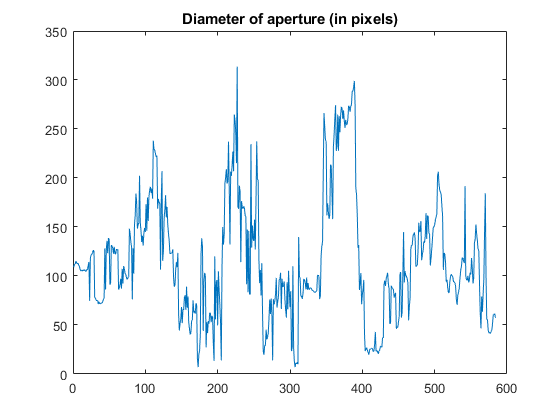


figure
plot(apertures)
title('Diameter of aperture (in pixels)')

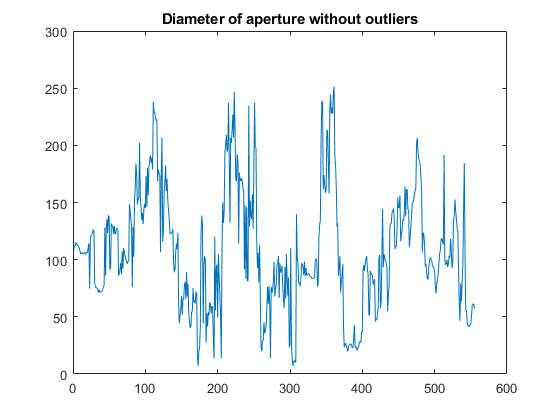


apertures = rmoutliers(apertures, 'quartiles');
plot(apertures)
title('Diameter of aperture without outliers')

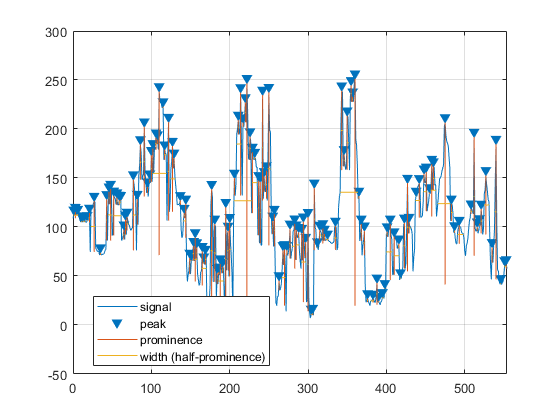


% Finding peaks
peaksIx = [1:size(apertures)];
[peaks, locs, p] = findpeaks(apertures,peaksIx,'Annotate','extents');
figure
findpeaks(apertures,peaksIx,'Annotate','extents')

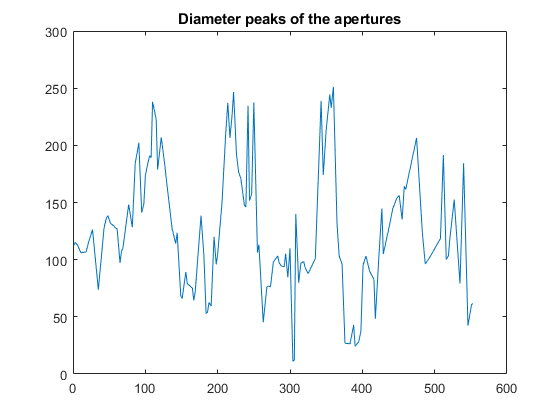


figure
plot(locs,peaks)
title('Diameter peaks of the apertures')

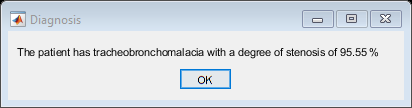


% Getting the biggest difference in the peaks
[minVal, minIx] = min(peaks);
[maxVal, maxIx] = max(peaks);
result = maxVal - minVal;

% Getting the difference on the degree of stenosis
degreeDiff = 100 - (minVal*100 / maxVal);

% Printing the results
formatStruct.Interpreter = 'tex';
formatStruct.WindowStyle = 'modal';
if degreeDiff > 50
    msgbox(sprintf('The patient has tracheobronchomalacia with a degree of stenosis of %.2f %%',degreeDiff),'Diagnosis',formatStruct)
else
    msgbox('The patient does not have tracheobronchomalacia','Diagnosis',formatStruct)
end


% \\\\\\\\\\\\\\\\\//////////////////

% cd ..\..\


function watershedSegmentation = watershedSegmentation(preProcessedFrame, frameCropped, frame)
    % ---------- Watershed ------------
    maximums = imregionalmax(preProcessedFrame);
%     figure
%     imshow(maximums)
%     title('Regional maximums')
    
    minimums = imregionalmin(preProcessedFrame);
%     figure
%     imshow(minimums)
%     title('Regional Minimums')
    
    minimum = extractClosestBlob(minimums, [size(frameCropped,1) / 2 size(frameCropped,2) / 2]);
%     figure
%     imshow(minimum)
%     title('Biggest minimum')
    
    D = bwdist(maximums | minimums);
    DL = watershed(D);
    bgm = DL == 0;
%     figure
%     imshow(bgm)
%     title('Watershed Ridge Lines')
    
    I2 = labeloverlay(frame,minimums | maximums);
%     figure
%     imshow(I2)
%     title('Regional Minimum and Maxima Superimposed on Frame)
    
    se2 = strel(ones(5,5));
    fgm2 = imclose(minimums | maximums,se2);
    fgm3 = imerode(fgm2,se2);
    fgm4 = bwareaopen(fgm3,20);
    I3 = labeloverlay(frame,fgm4);
%     figure
%     imshow(I3)
%     title('Modified Regional Maxima Superimposed on Frame')
    
    % Gradient of the image
    gmag = imgradient(frame);
%     figure
%     imshow(gmag,[]);
%     title('Image gradient')
    
    gmag2 = imimposemin(gmag, fgm4);
%     figure
%     imshow(gmag2,[])
%     title('Gradient with markers imposed')
    L = watershed(gmag2);
    labels = imdilate(L==0,ones(3,3)) + 2*(minimums | maximums) + 3*fgm4;
    I4 = labeloverlay(frame,labels);
%     figure
%     imshow(I4)
%     title('Markers and Object Boundaries Superimposed on rame')
    % labeling the watershed results
    Lrgb = label2rgb(L,'jet','w','shuffle');
%     figure
%     imshow(Lrgb)
%     title('Colored Watershed Label Matrix')
    % Getting the the value of the labels for the biggest minimum blob in the frame
    labelValue = L(minimum);
    % Getting the label with maximum ocurrence
    value = mode(labelValue);
    % Getting the watershed segmentation of the stenosis level
    watershedSegmentation= L == value;
%     figure
%     imshow(watershedSegmentation);
%     title('Watershed final mask')
    % ---------------------------------
end

function aperture = getStenosisDegree(frameCropped, frameMask, path)
    global S frameIx previousCentroid
    %  --------- Getting the degree of aperture and saving the image -------
        % Max diff result
        edgeDetected = edge(frameMask,"canny");
        frameOutlined = imoverlay(frameCropped,edgeDetected,'yellow');
        
        firstFig = figure('visible','off');
%         firstFig = figure;
        imshow(frameOutlined);
    
        stats = regionprops(frameMask, 'Centroid', 'BoundingBox', ...
            'Orientation', 'MinFeretProperties');
        
        % If there are more than on blob, I get the closest to the centroid of
        % the last frame with a valid centroid
        ixStats = 1; % Index of the stats struct
        if numel(stats) > 1
            centroids = [stats.Centroid];
            centroids = reshape(centroids,2,2).';
            [k, dist] = dsearchn(previousCentroid,centroids);
            [~, ixStats] = min(dist);
            centroid = stats(ixStats).Centroid;
        else
            centroid = stats.Centroid;
        end
        
        bbox = stats(ixStats).BoundingBox;
        orientation = stats(ixStats).Orientation; % Getting the perpendicular orientation
        minorAxisLen = stats(ixStats).MinFeretDiameter;
        
%         xCentroid = stats(ixStats).Centroid(1);
        xCentroid = bbox(1) + bbox(3)/2;
        yCentroid = stats(ixStats).Centroid(2);
        previousCentroid = [xCentroid yCentroid];
        
        % Calculating the aperture using the orientation of the blob
        % and the centroid
        sinOrient = sind(orientation);
        cosOrient = cosd(orientation);
        
        vertUpperDist = 0;
        vertLowerDist = 0;
        if orientation < 135 && orientation > -45 
            vertUpperDist = pdist([xCentroid, yCentroid; xCentroid, bbox(2), ],'euclidean');
            vertLowerDist = pdist([xCentroid, yCentroid; xCentroid, (bbox(2) + bbox(4))],'euclidean');
        else
            vertUpperDist = pdist([xCentroid, yCentroid; bbox(1), yCentroid, ],'euclidean');
            vertLowerDist = pdist([xCentroid, yCentroid; (bbox(1) + bbox(3)) ,yCentroid],'euclidean');
        end
        % Calculing the endpoints of the line of aperture from the centroid,
        % adding the relative distance to the bounding box plus a half
        xCoords(1) = xCentroid + (vertUpperDist + vertUpperDist/2) * sinOrient;
        yCoords(1) = yCentroid + (vertUpperDist + vertUpperDist/2) * cosOrient;
        xCoords(2) = xCentroid - (vertLowerDist + vertLowerDist/2) * sinOrient;
        yCoords(2) = yCentroid - (vertLowerDist + vertLowerDist/2) * cosOrient;
        
        % Distance between the two endpoints of the line
        nPoints = ceil(sqrt((xCoords(2) - xCoords(1)).^2 + (yCoords(2) - yCoords(1)).^2)) + 1;
        
        % X and Y values of the endpoints
        xvalues = round(linspace(xCoords(1), xCoords(2), nPoints));
        yvalues = round(linspace(yCoords(1), yCoords(2), nPoints));
        
        % Cropping the aperture pixels that surpass the bounding box of the blob
        if orientation < 135 && orientation > -45 
            xvalues(yvalues < bbox(2)) = [];
            yvalues(yvalues < bbox(2)) = [];
            xvalues(yvalues > (bbox(2) + bbox(4))) = [];
            yvalues(yvalues > (bbox(2) + bbox(4))) = [];
            
            yvalues(xvalues < bbox(1)) = [];
            xvalues(xvalues < bbox(1)) = [];
            yvalues(xvalues > (bbox(1) + bbox(3))) = [];
            xvalues(xvalues > (bbox(1) + bbox(3))) = [];
        else
            xvalues(yvalues < bbox(2)) = [];
            yvalues(yvalues < bbox(2)) = [];
            xvalues(yvalues > (bbox(2) + bbox(4))) = [];
            yvalues(yvalues > (bbox(2) + bbox(4))) = [];
            
            yvalues(xvalues < bbox(1)) = [];
            xvalues(xvalues < bbox(1)) = [];
            yvalues(xvalues > (bbox(1) + bbox(3))) = [];
            xvalues(xvalues > (bbox(1) + bbox(3))) = [];
        end
        
        % Mask the values of intercection of the line with the edge of the segmentation mask 
        lineMask = false(size(edgeDetected,1),size(edgeDetected,2));
        lineMask(sub2ind(size(lineMask), yvalues, xvalues)) = 1;
        
        % Dilating the line to ensure that it intersects with the edge
        lineMask = imdilate(lineMask,strel('line',5,orientation));
        lineMask = edgeDetected .* lineMask;
        
        % Values of the two farthest points of the line¡
        [row1,col1] = find(lineMask, 1, 'first');
        [row2,col2] = find(lineMask, 1, 'last');
        midpoint = ([row1 col1] + [row2 col2]).'/2;
        aperture = pdist([row1, col1; row2, col2],'euclidean');
        
        % Plot of all the data on top of the original image
        hold on;
        plot([col1,col2],[row1,row2],'c','LineWidth',2)
        plot(xCentroid, yCentroid, 'r+', 'LineWidth', 2, 'MarkerSize', 7)
        rectangle('Position',bbox,"EdgeColor",'b')
        title('Segmentation outline with the degree of stenosis');
        text(midpoint(2) + 20,midpoint(1),string(aperture),'Color',[0 1 1],'FontSize',8)
        saveas(firstFig,[pwd path S(frameIx).name]);
end

function mask = binBinarization(frame,bins)
    global previousThreshold
    [counts,binLocations] = imhist(frame,bins);
    % Getting first local maxima in the hist with a threshold of 500
    % I use this threshold to ignore small local peaks
    [pks,locs] = findpeaks(counts,'MinPeakHeight',6000);
    if not(isempty(pks)) 
        ix = locs(1) - 1; %indexing to the previous bin for the calculus
        % Setting the threshold using the % of divergence between bins
        countDiff = (counts(ix) * 100) / counts(ix + 1);
        binDiff = binLocations(ix + 1) - binLocations(ix);
        binThresh = binLocations(ix) + binDiff * ((100-countDiff)/100);       
    else
        diffs = diff(counts);
        [maxDiff, diffIx] = max(diffs(diffs>=0));
        countDiff = (counts(diffIx) * 100) / counts(diffIx + 1);
        binDiff = binLocations(diffIx + 1) - binLocations(diffIx);
        binThresh = binLocations(diffIx) + binDiff * ((100-countDiff)/100);
    end
    % The previous threshold is taken into account in order to get more
    % accurate results
    if previousThreshold ~= -1
        threshDiff = binThresh - previousThreshold;
        if threshDiff >= 0
            percentageOfDiff = previousThreshold*100 / binThresh;
            binThresh = binThresh - threshDiff*(percentageOfDiff/100);
        else
            percentageOfDiff = binThresh*100 / previousThreshold;
            binThresh = binThresh + abs(threshDiff)*(percentageOfDiff/100);
        end
    end
    previousThreshold = binThresh;
    mask = frame <= binThresh;    
end

function segmentationOutline(frame, segmentation)
    edgeDetected = edge(segmentation,"canny");
    frameOutlined = imoverlay(frame,edgeDetected,'yellow');
    imshow(frameOutlined);
end

function openClosedImage = openCloseByReconstruction(frame)    
    se = strel('disk',20);
    frameOpen = imopen(frame,se);
%     figure
%     imshow(frameOpen)
%     title('Opening')
    
    frameErode = imerode(frame,se);
    frameObR = imreconstruct(frameErode,frame);
%     figure
%     imshow(frameObR)
%     title('Opening-by-Reconstruction')
    
    frameOpCl = imclose(frameOpen,se);
%     figure
%     imshow(frameOpCl)
%     title('Opening-Closing')
    
    frameObRDilated = imdilate(frameObR,se);
    frameOCRecon = imreconstruct(imcomplement(frameObRDilated),imcomplement(frameObR));
    openClosedImage = imcomplement(frameOCRecon);
%     figure
%     imshow(openClosedImage)
%     title('Opening-Closing by Reconstruction')
end

function binaryImage = extractClosestBlob(binaryImage, point)
    try
      % Get all the Centroids
      [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
      blobStats = regionprops(labeledImage, 'Centroid');
      allCentroids = [blobStats.Centroid];
      allCentroids = reshape(allCentroids,2,[]).';
        
      % Get the closest Blob to the point
      [k, dist] = dsearchn(point,allCentroids);
      [~, ixStats] = min(dist);
      
      % Extract the blob using ismember().
      biggestBlob = ismember(labeledImage, ixStats);
      % Convert from integer labeled image into binary (logical) image.
      binaryImage = biggestBlob > 0;
      
    catch ME
      errorMessage = sprintf('Error in function extractClosestBlob().\n\nError Message:\n%s', ME.message);
      fprintf(1, '%s\n', errorMessage);
      uiwait(warndlg(errorMessage));
    end
end

function segmentFrame = getSegment(binFrame)
    % -------- Filling holes ----------
    filledFrame = imfill(binFrame,8,'holes');
%     imshow(filledFrame);
%     title('Binarization with filled holes');
%     figure
    % ---------------------------------
    
    % ---------- Closing gaps ---------
    % With disks
    % SE = strel('disk',15,8);
    % closedFrame = imclose(filledFrame,SE);
    % imshow(closedFrame); % Circle closed
    % closedFilledFrame = imfill(closedFrame,8,'holes');
    % imshow(closedFilledFrame);
    
    % With lines
    positiveSlope = strel('line',15,45);
    negativeSlope = strel('line',15,-45);
    horizontalLine = strel('line',15,0);
    verticalLine = strel('line',15,90);
    closedFrame=imclose(filledFrame,positiveSlope);
    closedFrame=imclose(closedFrame,negativeSlope);
    closedFrame=imclose(closedFrame,horizontalLine);
    closedFrame=imclose(closedFrame,verticalLine);
    closedFilledFrame = imfill(closedFrame,8,'holes');
%     imshow(closedFilledFrame);
%     title('Closed frame with gaps filled');
%     figure
    % ---------------------------------
    
    % -- Removing small Conn. Comp. ---
    props = regionprops(closedFilledFrame, 'Area');
    allAreas = [props.Area];
    cleanedFrame = bwareaopen(closedFilledFrame, ceil(max(allAreas)*0.75));
%     imshow(cleanedFrame);
%     title('Removal of unnecessary connected components and filling gaps');
%     figure
    % ---- Extracting largest Blobs ---
    % blobFrame = ExtractNLargestBlobs(cleanedFrame, 1);
    % imshow(blobFrame);
    
    positiveSlope = strel('line',25,45);
    negativeSlope = strel('line',25,-45);
    horizontal = strel('line',25,0);
    vertical = strel('line',25,90);
    closeBlobFrame=imclose(cleanedFrame,positiveSlope);
    closeBlobFrame=imclose(closeBlobFrame,negativeSlope);
    closeBlobFrame=imclose(closeBlobFrame,horizontal);
    closeBlobFrame=imclose(closeBlobFrame,vertical);
    closeBlobFrame = imfill(closeBlobFrame,8,'holes');
%     imshow(closeBlobFrame);
%     title('Final segmentation mask');
%     figure
    segmentFrame = closeBlobFrame;
    % ---------------------------------
    % ---------------------------------
    
    % ----- Threading the needle ------
    % ---------- Convex hull ----------
    % unionFrame = bwconvhull(blobFrame, 'Union');
    % imshow(unionFrame);
    % ---------------------------------
    % -------- Active Countour --------
    %numberOfIterations = 100;
    %bw = activecontour(frameRChannel, unionFrame, numberOfIterations, 'edge');
    %imshow(bw);
    % ---------------------------------
    % ---------------------------------
end